clear;
clc;


% image = imread('MapTest2.PNG');
% grayimage=im2gray('MapTest2.PNG')
% imshow(grayimage)
% imageNorm = double(grayimage)/255;
% imageOccupancy = 1-imageNorm
% map = occupancyMap(imageOccupancy,20);
% show(map)

%For Map1
image = imread('MapTest2.PNG');
grayimage = rgb2gray(image);
bwimage = grayimage < 0.5;
bwimage=bwimage*0.9

bwimage =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

grid = occupancyMap(bwimage);
grid

grid =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1
                 GridSize: [635 946]
             XLocalLimits: [0 946]
             YLocalLimits: [0 635]
             XWorldLimits: [0 946]
             YWorldLimits: [0 635]


%Defining Critical Points
x=[750;850] 

x =    750
   850


y=[350;100]

y =    350
   100


pvalue=[1;1]

pvalue =      1
     1


updateOccupancy(grid,[x y],pvalue)
setOccupancy(grid,[x y],1)
%Check for obstacle vs check for critical point
pocc = getOccupancy(grid,[400,150]) %Obs

pocc = 0.9000

pocc=getOccupancy(grid,[x y]) %Critical point probability check

pocc =     0.9990
    0.9990


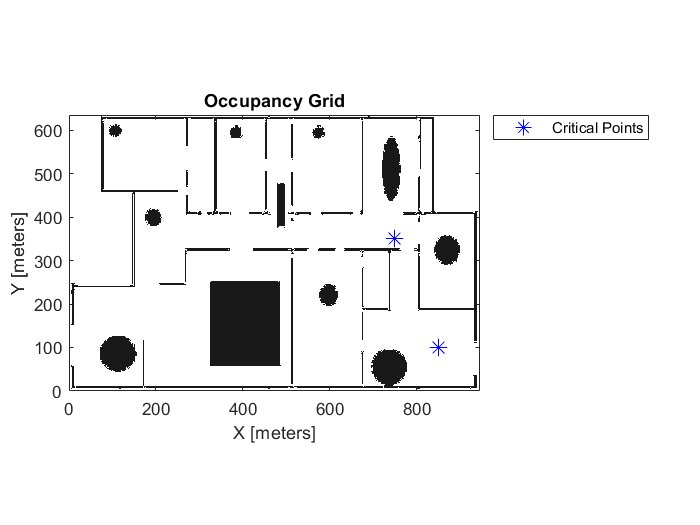

figure
show(grid)
hold on
plot(x,y,'*b','MarkerSize',10) % Critical Point Mark
legend('Critical Points',"Location","bestoutside")


%For Map2
image1 = imread('ForestMap.png');
grayimage = rgb2gray(image1);
bwimage = grayimage < 0.5;
bwimage=bwimage*0.9

bwimage =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         

grid1 = occupancyMap(bwimage);
grid1

grid1 =   occupancyMap with properties:

   mapLayer Properties
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000
    ProbabilitySaturation: [0.0010 0.9990]
                LayerName: 'probabilityLayer'
                 DataType: 'double'
             DefaultValue: 0.5000
      GridLocationInWorld: [0 0]
        GridOriginInLocal: [0 0]
       LocalOriginInWorld: [0 0]
               Resolution: 1
                 GridSize: [629 1350]
             XLocalLimits: [0 1350]
             YLocalLimits: [0 629]
             XWorldLimits: [0 1350]
             YWorldLimits: [0 629]


%Defining Critical Points
x1=[1300;850] 

x1 =         1300
         850


y1=[550;100]

y1 =    550
   100


updateOccupancy(grid,[x1 y1],pvalue)
setOccupancy(grid,[x1 y1],1)
%Check for obstacle vs check for critical point
pocc = getOccupancy(grid,[400,150]) %Obs

pocc = 0.9000

pocc=getOccupancy(grid,[x1 y1]) %Critical point probability check

pocc =     0.5000
    0.9990


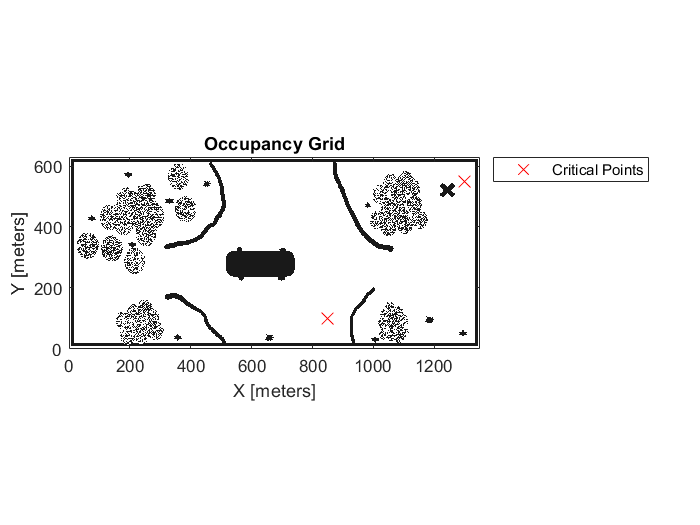

figure
show(grid1)
hold on
plot(x1,y1,'xr','MarkerSize',10) % Critical Point Mark
legend('Critical Points',"Location","bestoutside")